# Multi-class Classification

There are 5000 training examples in ex3data1.mat, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is “unrolled” into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix X. This gives us a 5000 by 400 matrix X where every row is a training example for a handwritten digit image. 

The second part of the training set is a 5000-dimensional vector y that contains labels for the training set. A  “0” digit is labeled as “10”, while the digits “1” to “9” are labeled as “1” to “9” in their natural order.

## 1 Visualizing Data

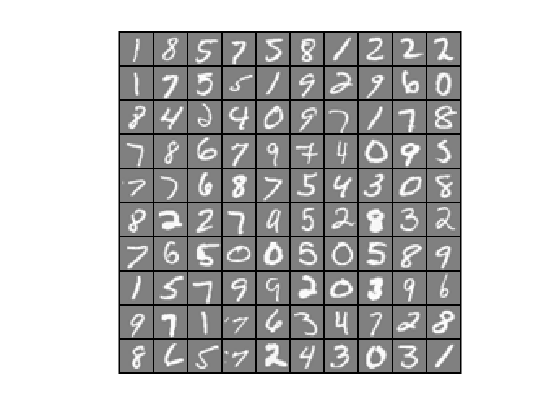

% Initialization
clear; 
close all; 
clc;

load('ex3data1.mat');     % training data stored in arrays X, y.
m = size(X, 1);
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

## 2 One-vs-All Training

num_labels = 10;          % 10 labels, from 1 to 10.
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

Iteration     1 | Cost: 2.802128e-01
Iteration     2 | Cost: 9.454389e-02
Iteration     3 | Cost: 5.704641e-02
Iteration     4 | Cost: 4.688190e-02
Iteration     5 | Cost: 3.759021e-02
Iteration     6 | Cost: 3.522008e-02
Iteration     7 | Cost: 3.234531e-02
Iteration     8 | Cost: 3.145034e-02
Iteration     9 | Cost: 3.008919e-02
Iteration    10 | Cost: 2.994639e-02
Iteration    11 | Cost: 2.678528e-02
Iteration    12 | Cost: 2.660323e-02
Iteration    13 | Cost: 2.493301e-02
Iteration    14 | Cost: 2.475211e-02
Iteration    15 | Cost: 2.318421e-02
Iteration    16 | Cost: 2.287050e-02
Iteration    17 | Cost: 2.160258e-02
Iteration    18 | Cost: 2.120371e-02
Iteration    19 | Cost: 2.064125e-02
Iteration    20 | Cost: 2.055695e-02
Iteration    21 | Cost: 2.045466e-02
Iteration    22 | Cost: 2.029177e-02
Iteration    23 | Cost: 2.005296e-02
Iteration    24 | Cost: 1.995949e-02
Iteration    25 | Cost: 1.982849e-02
Iteration    26 | Cost: 1.975129e-02
Iteration    27 | Cost: 1.897815e-02
I

## 3 Predict for One-Vs-All

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.040000


## 4 Function

function g = sigmoid(z)
%SIGMOID Compute sigmoid functoon
%   J = SIGMOID(z) computes the sigmoid of z.
g = 1.0 ./ (1.0 + exp(-z));
end

function [J, grad] = lrCostFunction(theta, X, y, lambda)
%LRCOSTFUNCTION Compute cost and gradient for logistic regression with regularization
%   J = LRCOSTFUNCTION(theta, X, y, lambda) computes the cost of using
%   theta as the parameter for regularized logistic regression and the
%   gradient of the cost w.r.t. to the parameters. 
m = length(y); 
J = (-y'*log(sigmoid(X*theta))-(1-y')*log(1-sigmoid(X*theta)))/m + lambda/(2*m)*theta(2:end,:)'*theta(2:end,:);
grad_reg = zeros(size(theta));
grad_reg(2:end) = lambda/m*theta(2:end,:);
grad = X'*(sigmoid(X*theta)-y)./m + grad_reg;
grad = grad(:);
end


function [all_theta] = oneVsAll(X, y, num_labels, lambda)
%ONEVSALL trains multiple logistic regression classifiers and returns all
%the classifiers in a matrix all_theta, where the i-th row of all_theta 
%corresponds to the classifier for label i
%   [all_theta] = ONEVSALL(X, y, num_labels, lambda) trains num_labels
%   logistic regression classifiers and returns each of these classifiers
%   in a matrix all_theta, where the i-th row of all_theta corresponds 
%   to the classifier for label i

% Some useful variables
m = size(X, 1);
n = size(X, 2);

% You need to return the following variables correctly 
all_theta = zeros(num_labels, n + 1);

% Add ones to the X data matrix
X = [ones(m, 1) X];

for k = 1:num_labels
    initial_theta = zeros(n + 1, 1);
    options = optimset('GradObj', 'on', 'MaxIter', 50);
    [theta] = fmincg (@(t)(lrCostFunction(t, X, (y == k), lambda)), initial_theta, options);
    all_theta(k,:) = theta';
end

end

function p = predictOneVsAll(all_theta, X)
%PREDICT Predict the label for a trained one-vs-all classifier. The labels 
%are in the range 1..K, where K = size(all_theta, 1). 
%  p = PREDICTONEVSALL(all_theta, X) will return a vector of predictions
%  for each example in the matrix X. Note that X contains the examples in
%  rows. all_theta is a matrix where the i-th row is a trained logistic
%  regression theta vector for the i-th class. You should set p to a vector
%  of values from 1..K (e.g., p = [1; 3; 1; 2] predicts classes 1, 3, 1, 2
%  for 4 examples) 
m = size(X, 1);
X = [ones(m, 1) X];
[~,p] = max(sigmoid(X*all_theta'),[],2);
end